syms T V

R = 8.314;
Ttriple = 180.97;
Tcrit = 437.22;
Pcrit = 5.34e+6;
antA = 4.29371;
antB = 995.445;
antC = -47.869;
Pant = @(T) (10^5)*10^(antA - (antB/(T + antC)));
b = 0.0778*R*Tcrit/Pcrit;

omega = -1 - log10(Pant(0.7*Tcrit)/Pcrit);
k_small = 0.37464 + 1.5422*omega - 0.26992*omega^2;
alpha_T = @(T) (1 + k_small*(1 - sqrt(T./Tcrit)))^2;
a_T = @(T) (0.45724*(R^2)*(Tcrit^2)/Pcrit) * alpha_T(T);

Prb = @(T,V) R*T./(V - b) - a_T(T)/(V.*(V + b) + b*(V - b));

Trange = Tcrit*[1,1.1,1.25,1.5,1.75,2];

Prange = linspace(0,8*Pcrit,100);

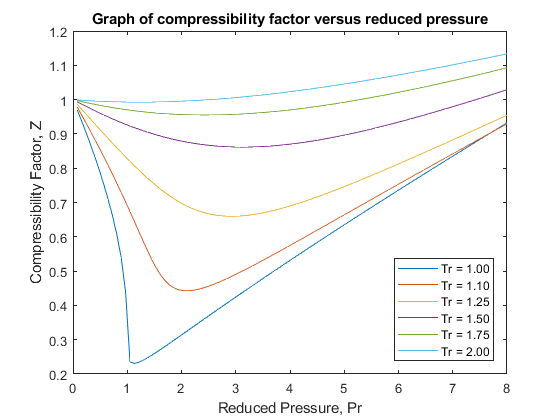

for i = 1:length(Trange)
    Zarray = [];
    P_newarray = [];
    for j = 1:length(Prange)
        Vreal = vpasolve(Prb(Trange(i),V) == Prange(j),V,[0 Inf])';
        
        if numel(Vreal) == 1
            Zarray = [Zarray Prange(j)*Vreal(1)/(R*Trange(i))];
            P_newarray = [P_newarray Prange(j)];
        elseif numel(Vreal) == 2
            Zarray = [Zarray Prange(j)*Vreal(1)/(R*Trange(i)) Prange(j)*Vreal(2)/(R*Trange(i))];
            P_newarray = [P_newarray Prange(j) Prange(j)];   
        end
    end
    if i == 1
        Z1 = double(Zarray');
    elseif i == 2
        Z2 = double(Zarray');
    elseif i == 3
        Z3 = double(Zarray');
    elseif i == 4
        Z4 = double(Zarray');
    elseif i == 5
        Z5 = double(Zarray');
    elseif i == 6
        Z6 = double(Zarray');
    end
    
    [P_newarray,sortIdx] = sort(P_newarray);
    Zarray = Zarray(sortIdx);
    plot(P_newarray/Pcrit,Zarray)
    hold on
    
end
legend({'Tr = 1.00','Tr = 1.10','Tr = 1.25','Tr = 1.50','Tr = 1.75','Tr = 2.00'},'Location','southeast')
xlabel('Reduced Pressure, Pr')
ylabel('Compressibility Factor, Z')
title('Graph of compressibility factor versus reduced pressure')
hold off

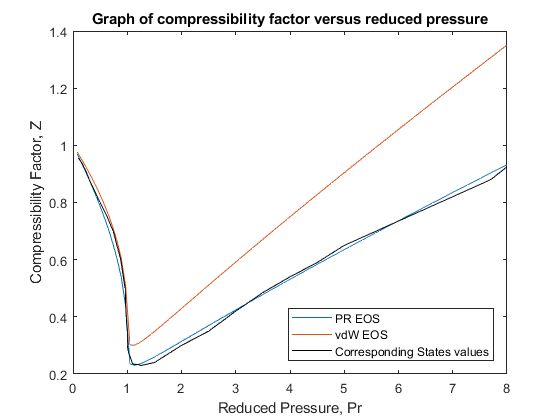

Zarray = [];
P_newarray = [];
for i = 1:length(Prange)
    Vreal = vpasolve(Prb(Tcrit,V) == Prange(i),V,[0 Inf])';
    if numel(Vreal) == 1
        Zarray = [Zarray Prange(i)*Vreal(1)/(R*Tcrit)];
        P_newarray = [P_newarray Prange(i)];
    elseif numel(Vreal) == 2
        Zarray = [Zarray Prange(i)*Vreal(1)/(R*Tcrit) Prange(i)*Vreal(2)/(R*Tcrit)];
        P_newarray = [P_newarray Prange(i) Prange(i)];
    end
end

[P_newarray,sortIdx] = sort(P_newarray);
Zarray = Zarray(sortIdx);

plot(P_newarray/Pcrit,Zarray)
hold on

a_vdW = 27*R^2*Tcrit^2/(64*Pcrit);
b_vdW = R*Tcrit/(8*Pcrit);
PvdW = @(T,V) R*T./(V - b_vdW) - a_vdW/V.^2;

Zarray = [];
P_newarray = [];

for i = 1:length(Prange)
    Vreal = vpasolve(PvdW(Tcrit,V) == Prange(i),V,[0 Inf])';
    if numel(Vreal) == 1
        Zarray = [Zarray Prange(i)*Vreal(1)/(R*Tcrit)];
        P_newarray = [P_newarray Prange(i)];
    elseif numel(Vreal) == 2
        Zarray = [Zarray Prange(i)*Vreal(1)/(R*Tcrit) Prange(i)*Vreal(2)/(R*Tcrit)];
        P_newarray = [P_newarray Prange(i) Prange(i)];
    elseif numel(Vreal) == 3
        Zarray = [Zarray Prange(i)*Vreal(1)/(R*Tcrit) Prange(i)*Vreal(2)/(R*Tcrit) Prange(i)*Vreal(3)/(R*Tcrit)];
        P_newarray = [P_newarray Prange(i) Prange(i) Prange(i)];
    end
end

[P_newarray,sortIdx] = sort(P_newarray);
Zarray = Zarray(sortIdx);
plot(P_newarray/Pcrit,Zarray)

Z_book = [0.955 0.942 0.925 0.905 0.88 0.86 0.84 0.82 0.8 0.75 0.7 0.6 0.5 0.4 0.35 0.3 0.278 0.235 0.233 0.23 0.24 0.3 0.35 0.42 0.485 0.54 0.59 0.65 0.88 0.925];
P_book = [0.1 0.15 0.2 0.25 0.3 0.35 0.4 0.45 0.5 0.63 0.74 0.88 0.96 0.98 1 1 1.02 1.1 1.2 1.25 1.5 2 2.5 3 3.5 4 4.5 5 7.7 8];

plot(P_book,Z_book,'k-')

xlabel('Reduced Pressure, Pr')
ylabel('Compressibility Factor, Z')
title('Graph of compressibility factor versus reduced pressure')
legend({'PR EOS','vdW EOS','Corresponding States values'},'Location','southeast')